%% Post-Processing SD Card Data for Formula Student Telemetry
% Plots all data vs. sample number instead of time.

clear; close all; clc;

%% CONFIG
filename = 'DATALOG.csv';  % Path to your CSV file
window   = 10;             % Moving-average window for temperature smoothing
rho      = 1.225;          % Air density (kg/m³)

%% 1) IMPORT TABLE WITH TIMESTAMP AS TEXT
opts = detectImportOptions(filename, 'NumHeaderLines', 0);

% If your CSV has a header row, uncomment and adjust the next line:
% opts.VariableNamesLine = 1;

% Ensure we have at least 9 variables; name them Var1...Var9 if no header
if numel(opts.VariableNames) < 9
    opts.VariableNames = strcat("Var", string(1:9));
end

% Force column 9 (timestamp) to be read as text
opts = setvaropts(opts, opts.VariableNames{9}, 'Type', 'string');
opts.ExtraColumnsRule = 'ignore';
opts.MissingRule      = 'fill';

Ttbl = readtable(filename, opts);

%% 2) EXTRACT COLUMNS & CONVERT TIMESTAMP
pressure_Pa = Ttbl{:,1};   % Differential pressure in Pa
temp_C      = Ttbl{:,2};   % Temperature in °C

accX = Ttbl{:,3};          % Accelerometer X
accY = Ttbl{:,4};          % Accelerometer Y
accZ = Ttbl{:,5};          % Accelerometer Z

gyroX = Ttbl{:,6};         % Gyro X
gyroY = Ttbl{:,7};         % Gyro Y
gyroZ = Ttbl{:,8};         % Gyro Z

timeStr = Ttbl{:,9};       % Timestamp strings (hh:mm:ss.SSS)
t_datetime = datetime(timeStr, 'InputFormat', 'HH:mm:ss.SSS');
% We won't use T for plotting, but you can still compute it if needed:
T = seconds(t_datetime - t_datetime(1));

%% 3) SAMPLE INDEX VECTOR
N = height(Ttbl);
samples = (1:N)';

%% 4) SANITY CHECK
fprintf('Imported %d samples.\n', N);

Imported 2202 samples.


fprintf('Pressure range: %.2f → %.2f Pa\n', min(pressure_Pa), max(pressure_Pa));

Pressure range: -1053.27 → 1253.67 Pa


fprintf('Temperature range: %.2f → %.2f °C\n', min(temp_C), max(temp_C));

Temperature range: 0.00 → 0.00 °C


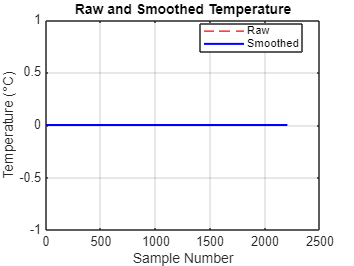

fprintf('\n');

%% 5) SMOOTH TEMPERATURE (MOVING AVERAGE)
temp_smooth = movmean(temp_C, window);

%% 6) PLOT TEMPERATURE vs. Sample
figure('Name','Temperature vs Sample','NumberTitle','off');
plot(samples, temp_C,  'r--', 'LineWidth',1);
hold on;
plot(samples, temp_smooth,'b-', 'LineWidth',1.5);
xlabel('Sample Number');
ylabel('Temperature (°C)');
title('Raw and Smoothed Temperature');
legend('Raw','Smoothed','Location','best');
grid on;
hold off;

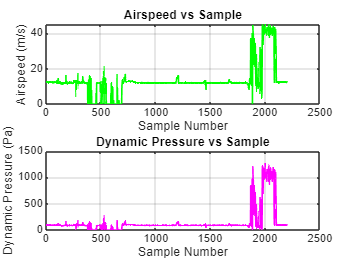


%% 7) COMPUTE AIRSPEED & DYNAMIC PRESSURE
airspeed  = sqrt( max((2 .* pressure_Pa) ./ rho, 0) );
q_dynamic = 0.5 * rho .* airspeed.^2;

%% 8) PLOT AIRSPEED & DYNAMIC PRESSURE vs. Sample
figure('Name','Airspeed & Dynamic Pressure vs Sample','NumberTitle','off');
subplot(2,1,1);
plot(samples, airspeed, 'g', 'LineWidth',1.2);
xlabel('Sample Number'); ylabel('Airspeed (m/s)');
title('Airspeed vs Sample'); grid on;

subplot(2,1,2);
plot(samples, q_dynamic, 'm', 'LineWidth',1.2);
xlabel('Sample Number'); ylabel('Dynamic Pressure (Pa)');
title('Dynamic Pressure vs Sample'); grid on;

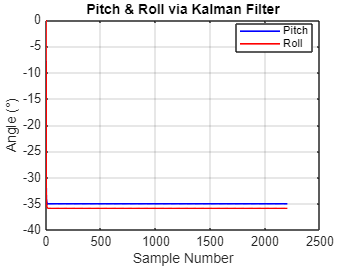


%% 9) KALMAN FILTER FOR ORIENTATION (PITCH & ROLL)
dt = mean(diff(T));  % timestep based on actual time, if consistent

% Accelerometer-derived angle estimates (degrees)
angle_acc_pitch = atan2d(accX, sqrt(accY.^2 + accZ.^2));
angle_acc_roll  = atan2d(accY, sqrt(accX.^2 + accZ.^2));

% Preallocate
angle_pitch = zeros(N,1);
angle_roll  = zeros(N,1);

% Kalman parameters
Pp = 1; Pr = 1;
Q  = 0.01; R  = 0.1;

for i = 2:N
    % 1) Predict step (integrate gyro)
    pred_pitch = angle_pitch(i-1) + dt * gyroY(i);
    pred_roll  = angle_roll(i-1)  + dt * gyroX(i);
    % 2) Kalman gains
    Kp = Pp / (Pp + R);
    Kr = Pr / (Pr + R);
    % 3) Update with accel-measured angle
    angle_pitch(i) = pred_pitch + Kp * (angle_acc_pitch(i) - pred_pitch);
    angle_roll(i)  = pred_roll  + Kr * (angle_acc_roll(i)  - pred_roll);
    % 4) Covariance update
    Pp = (1 - Kp) * Pp + Q;
    Pr = (1 - Kr) * Pr + Q;
end

%% 10) PLOT FILTERED ORIENTATION vs. Sample
figure('Name','Orientation (Kalman) vs Sample','NumberTitle','off');
plot(samples, angle_pitch, 'b', 'LineWidth',1.2);
hold on;
plot(samples, angle_roll,  'r', 'LineWidth',1.2);
xlabel('Sample Number');
ylabel('Angle (°)');
title('Pitch & Roll via Kalman Filter');
legend('Pitch','Roll','Location','best');
grid on;
hold off;